
%Problem 1
syms theta1 theta2 theta3 theta4
c1 = cos(theta1); s1 = sin(theta1);
c2 = cos(theta2); s2 = sin(theta2);
c3 = cos(theta3); s3 = sin(theta3);
c4 = cos(theta4); s4 = sin(theta4);
%% Computes the Ti
T01 = [c1 0 s1 0;
    s1 0 -c1 0;
    0 1 0 50
    0 0 0 1];

T12 = [c2 -s2 0 93*c2;
    s2 c2 0 93*s2;
    0 0 1 0;
    0 0 0 1];

T23 = [c3 -s3 0 93*c3;
    s3 c3 0 93*s3;
    0 0 1 0;
    0 0 0 1];

T34 = [c4 -s4 0 50*c4;
    s4 c4 0 50*s4;
    0 0 1 0;
    0 0 0 1];

T45 = [1 0 0 -15
    0 1 0 45
    0 0 1 0
    0 0 0 1];

%% Computes T0i

T02 = T01*T12;
T03 = T02*T23;
T04 = T03*T34

T05 = T04*T45

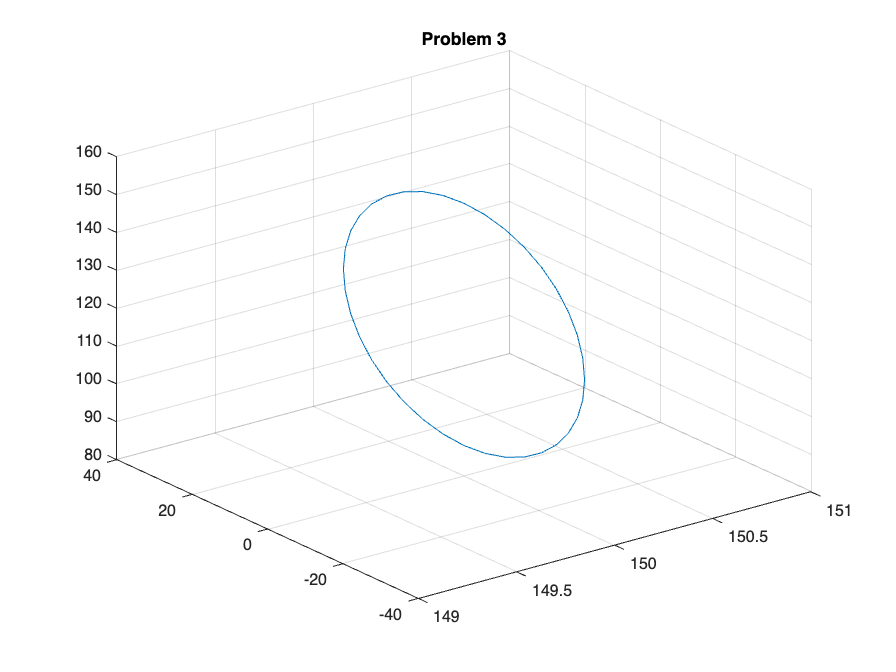

%Problem 3
%% Robot parameters
d1 = 50;
a2 = 93;
a3 = 93;
a4 = 50;

%% Problem 3 parameters
angle = linspace(0,2*pi,37)';

[x, y, z] =circleCoordinates(angle);

%% Joint angles calculation from stilus tip coordinates. (last link horizontal)
[thetas_1_deg, thetas_2_deg, thetas_1_rad, thetas_2_rad] = jointAnglesCalculation(x,y,z);
figure
plot3(x,y,z)
grid on
title("Problem 3")

thetas_2_rad

thetas_2_rad =     0.2102    1.4302   -1.6699    0.2397
    0.2071    1.4437   -1.6242    0.1805
    0.1978    1.4556   -1.5789    0.1233
    0.1827    1.4656   -1.5354    0.0698
    0.1620    1.4737   -1.4952    0.0214
    0.1363    1.4801   -1.4597   -0.0204
    0.1063    1.4848   -1.4304   -0.0544
    0.0728    1.4880   -1.4084   -0.0795
    0.0370    1.4898   -1.3949   -0.0950
    0.0000    1.4904   -1.3903   -0.1002


%Problem 4 
[J4_1, J5_1] = JacobianMatrix(thetas_2_rad(1,1),thetas_2_rad(1,2),thetas_2_rad(1,3),thetas_2_rad(1,4))

J4_1 =   -32.0000  -68.4595   21.5960         0
  150.0000  -14.6047    4.6071         0
         0  153.3754  140.3404   50.0000
         0    0.2086    0.2086    0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000         0         0         0


J5_1 =   -28.8704 -112.4692  -22.4137  -44.0097
  135.3301  -23.9934   -4.7816   -9.3887
         0  138.3754  125.3404   35.0000
         0    0.2086    0.2086    0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000         0         0         0


[J4_2, J5_2] = JacobianMatrix(thetas_2_rad(10,1),thetas_2_rad(10,2),thetas_2_rad(10,3),thetas_2_rad(10,4))

J4_2 =    -0.0000 -102.0000   -9.3002         0
  150.0000   -0.0000   -0.0000         0
         0  150.0000  142.5338   50.0000
         0    0.0000    0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


J5_2 =    -0.0000 -147.0000  -54.3002  -45.0000
  135.0000   -0.0000   -0.0000   -0.0000
         0  135.0000  127.5338   35.0000
         0    0.0000    0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


[J4_pi, J5_pi] = JacobianMatrix(thetas_2_rad(19,1),thetas_2_rad(19,2),thetas_2_rad(19,3),thetas_2_rad(19,4))

J4_pi =    32.0000  -68.4595   21.5960         0
  150.0000   14.6047   -4.6071         0
         0  153.3754  140.3404   50.0000
         0   -0.2086   -0.2086   -0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000         0         0         0


J5_pi =    28.8704 -112.4692  -22.4137  -44.0097
  135.3301   23.9934    4.7816    9.3887
         0  138.3754  125.3404   35.0000
         0   -0.2086   -0.2086   -0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000         0         0         0


[J4_3, J5_3] = JacobianMatrix(thetas_2_rad(28,1),thetas_2_rad(28,2),thetas_2_rad(28,3),thetas_2_rad(28,4))

J4_3 =     0.0000  -38.0000   52.1173         0
  150.0000    0.0000   -0.0000         0
         0  150.0000  127.0246   50.0000
         0   -0.0000   -0.0000   -0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


J5_3 =     0.0000  -83.0000    7.1173  -45.0000
  135.0000    0.0000   -0.0000    0.0000
         0  135.0000  112.0246   35.0000
         0   -0.0000   -0.0000   -0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0



[J4_pi4, J5_pi4] = JacobianMatrix(thetas_2_rad(5,1),thetas_2_rad(5,2),thetas_2_rad(5,3),thetas_2_rad(5,4));
[J4_3pi4, J5_3pi4] = JacobianMatrix(thetas_2_rad(15,1),thetas_2_rad(15,2),thetas_2_rad(15,3),thetas_2_rad(15,4));
[J4_5pi4, J5_5pi4] = JacobianMatrix(thetas_2_rad(24,1),thetas_2_rad(24,2),thetas_2_rad(24,3),thetas_2_rad(24,4));
[J4_7pi4, J5_7pi4] = JacobianMatrix(thetas_2_rad(33,1),thetas_2_rad(33,2),thetas_2_rad(33,3),thetas_2_rad(33,4));

%Problem 5
syms wx
syms wy
syms wz
R90 = [1 0 0; 0 0 -1; 0 1 0]; %Rotation matrix at phi= pi/2
Skew = [0 -wz wy; wz 0 -wx; -wy wx 0];
Rderiv = Skew*R90;
xderiv = Rderiv(:, 1);
wy = 0;
J4_2;
result = [0;-3;0;0;0;0];
q_dot_90deg = J4_2\result %Velocity q_dot at phi = pi/2

q_dot_90deg =    -0.0200
    0.0000
   -0.0000
    0.0000


%Problem 6
syms A10 A11 A12 A13 A14 A15; 
l0= [0;0;0;0;0;0];  %V at phi = 0
l2 = [0;-25;0;0;0;0]; %V at phi = pi/2
qdot0 = J4_1\l0; %q_dot at phi = 0
qdot2 = J4_2\l2; % q_dot at phi = pi/2
%define matrix system of equations 
Y= [1 0 0 0 0 0; 0 1 0 0 0 0; 0 0 2 0 0 0; 1 2 4 8 16 32; 0 1 4 12 32 80; 0 0 2 12 48 160];
res = [thetas_2_rad(1,1); qdot0(1,1); 0; thetas_2_rad(10,1); qdot2(1,1); 0];
res = Y\res; %System Solution 
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

syms A20 A21 A22 A23 A24 A25;
res = [thetas_2_rad(1,2); qdot0(2,1); 0; thetas_2_rad(10,2); qdot2(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

syms A30 A31 A32 A33 A34 A35;
res = [thetas_2_rad(1,3); qdot0(3,1); 0; thetas_2_rad(10,3); qdot2(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

syms A40 A41 A42 A43 A44 A45;
res = [thetas_2_rad(1,4); qdot0(4,1); 0; thetas_2_rad(10,4); qdot2(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

A =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45]

A =     0.2102   -0.0000         0   -0.0961    0.0512   -0.0082
    1.4302    0.0000         0    0.0753   -0.0565    0.0113
   -1.6699   -0.0000         0    0.3496   -0.2622    0.0524
    0.2397    0.0000         0   -0.4249    0.3187   -0.0637



%------B-------------------------------------------------------------------

l2= [0;-25;0;0;0;0];
l4 = [0;0;-25;0;0;0];
qdot2 = J4_2\l2;
qdot4 = J4_pi\l4;
res = [thetas_2_rad(10,1); qdot2(1,1); 0; thetas_2_rad(19,1); qdot4(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(10,2); qdot2(2,1); 0; thetas_2_rad(19,2); qdot4(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(10,3); qdot2(3,1); 0; thetas_2_rad(19,3); qdot4(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

res = [thetas_2_rad(10,4); qdot2(4,1); 0; thetas_2_rad(19,4); qdot4(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

B =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45]

B =     0.0000   -0.1667         0   -0.0127    0.0304   -0.0082
    1.4904    0.0000         0   -0.0112    0.0004    0.0007
   -1.3903    0.0000         0   -0.1462    0.0842   -0.0143
   -0.1002   -0.0000         0    0.1574   -0.0846    0.0136



%-----------__C-------------------------------------------------------------------

l4= [0;0;-25;0;0;0];
l6 = [0;25;0;0;0;0];
qdot4 = J4_pi\l4;
qdot6 = J4_3\l6;
res = [thetas_2_rad(19,1); qdot4(1,1); 0; thetas_2_rad(28,1); qdot6(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(19,2); qdot4(2,1); 0; thetas_2_rad(28,2); qdot6(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(19,3); qdot4(3,1); 0; thetas_2_rad(28,3); qdot6(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

res = [thetas_2_rad(19,4); qdot4(4,1); 0; thetas_2_rad(28,4); qdot6(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

C =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45]

C =    -0.2102         0         0    0.0961   -0.0512    0.0082
    1.4302   -0.0641         0   -0.0400    0.0381   -0.0084
   -1.6699   -0.2033         0   -0.0027    0.0274   -0.0080
    0.2397    0.2675         0    0.0427   -0.0655    0.0164



%---------------__D-----------------------------------------------------------

l6= [0;25;0;0;0;0];
l8 = [0;0;0;0;0;0];
qdot6 = J4_3\l6;
qdot8 = J4_1\l8;
res = [thetas_2_rad(28,1); qdot6(1,1); 0; thetas_2_rad(37,1); qdot8(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(28,2); qdot6(2,1); 0; thetas_2_rad(37,2); qdot8(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(28,3); qdot6(3,1); 0; thetas_2_rad(37,3); qdot8(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);


res = [thetas_2_rad(28,4); qdot6(4,1); 0; thetas_2_rad(37,4); qdot8(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

D =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45]

D =    -0.0000    0.1667         0    0.0127   -0.0304    0.0082
    1.3212         0         0    0.1363   -0.1022    0.0204
   -1.9160         0         0    0.3077   -0.2307    0.0461
    0.5949    0.0000         0   -0.4439    0.3329   -0.0666


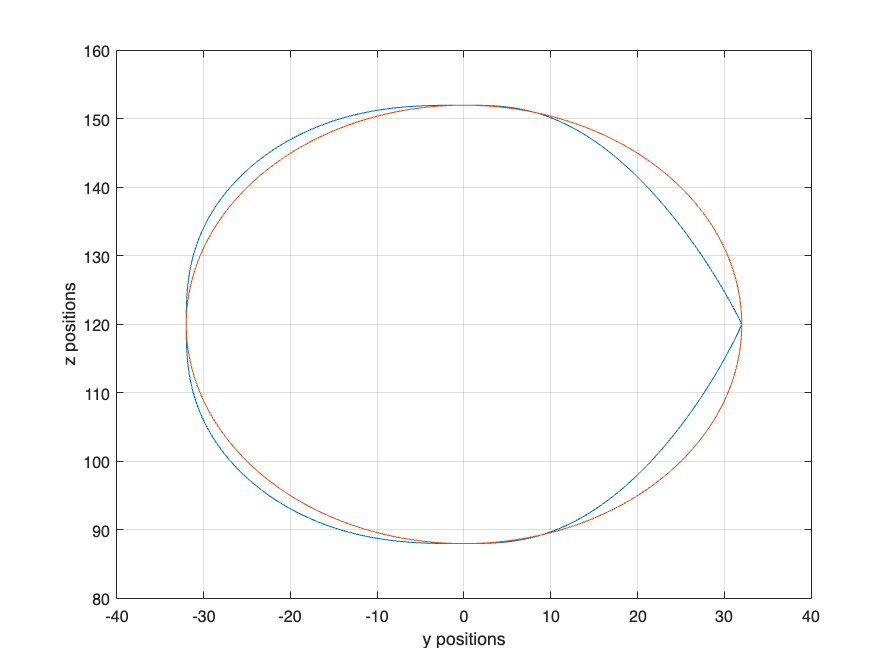

%Problem 7

t1 = linspace(0, 2, 100); % define time variable 

%define q, q_dot & q_dot_dot with interpolation functions 

q1_1 = A(1,1)+A(1,2).*t1+A(1,3).*t1.^2+A(1,4)*t1.^3+A(1,5).*t1.^4+A(1,6).*t1.^5; 
q1_1dot= A(1,2)+2*A(1,3).*t1+3*A(1,4)*t1.^2+4*A(1,5).*t1.^3+5*A(1,6).*t1.^4;
q1_1dotdot= 2*A(1,3)+6*A(1,4)*t1+12*A(1,5).*t1.^2+20*A(1,6).*t1.^3;

q2_1 = A(2,1)+A(2,2).*t1+A(2,3).*t1.^2+A(2,4)*t1.^3+A(2,5).*t1.^4+A(2,6).*t1.^5;
q2_1dot= A(2,2)+2*A(2,3).*t1+3*A(2,4)*t1.^2+4*A(2,5).*t1.^3+5*A(2,6).*t1.^4;
q2_1dotdot= 2*A(2,3)+6*A(2,4)*t1+12*A(2,5).*t1.^2+20*A(2,6).*t1.^3;

q3_1 = A(3,1)+A(3,2).*t1+A(3,3).*t1.^2+A(3,4)*t1.^3+A(3,5).*t1.^4+A(3,6).*t1.^5;
q3_1dot= A(3,2)+2*A(3,3).*t1+3*A(3,4)*t1.^2+4*A(3,5).*t1.^3+5*A(3,6).*t1.^4;
q3_1dotdot= 2*A(3,3)+6*A(3,4)*t1+12*A(3,5).*t1.^2+20*A(3,6).*t1.^3;

q4_1 = A(4,1)+A(4,2).*t1+A(4,3).*t1.^2+A(4,4)*t1.^3+A(4,5).*t1.^4+A(4,6).*t1.^5;
q4_1dot= A(4,2)+2*A(4,3).*t1+3*A(4,4)*t1.^2+4*A(4,5).*t1.^3+5*A(4,6).*t1.^4;
q4_1dotdot= 2*A(4,3)+6*A(4,4)*t1+12*A(4,5).*t1.^2+20*A(4,6).*t1.^3;

%t1 = linspace(2, 4, 50);
q1_2 = B(1,1)+B(1,2).*t1+B(1,3).*t1.^2+B(1,4)*t1.^3+B(1,5).*t1.^4+B(1,6).*t1.^5;
q1_2dot= B(1,2)+2*B(1,3).*t1+3*B(1,4)*t1.^2+4*B(1,5).*t1.^3+5*B(1,6).*t1.^4;
q1_2dotdot= 2*B(1,3)+6*B(1,4)*t1+12*B(1,5).*t1.^2+20*B(1,6).*t1.^3;

q2_2 = B(2,1)+B(2,2).*t1+B(2,3).*t1.^2+B(2,4)*t1.^3+B(2,5).*t1.^4+B(2,6).*t1.^5;
q2_2dot= B(2,2)+2*B(2,3).*t1+3*B(2,4)*t1.^2+4*B(2,5).*t1.^3+5*B(2,6).*t1.^4;
q2_2dotdot= 2*B(2,3)+6*B(2,4)*t1+12*B(2,5).*t1.^2+20*B(2,6).*t1.^3;

q3_2 = B(3,1)+B(3,2).*t1+B(3,3).*t1.^2+B(3,4)*t1.^3+B(3,5).*t1.^4+B(3,6).*t1.^5;
q3_2dot= B(3,2)+2*B(3,3).*t1+3*B(3,4)*t1.^2+4*B(3,5).*t1.^3+5*B(3,6).*t1.^4;
q3_2dotdot= 2*B(3,3)+6*B(3,4)*t1+12*B(3,5).*t1.^2+20*B(3,6).*t1.^3;

q4_2 = B(4,1)+B(4,2).*t1+B(4,3).*t1.^2+B(4,4)*t1.^3+B(4,5).*t1.^4+B(4,6).*t1.^5;
q4_2dot= B(4,2)+2*B(4,3).*t1+3*B(4,4)*t1.^2+4*B(4,5).*t1.^3+5*B(4,6).*t1.^4;
q4_2dotdot= 2*B(4,3)+6*B(4,4)*t1+12*B(4,5).*t1.^2+20*B(4,6).*t1.^3;

%t1 = linspace(4, 6, 50);
q1_3 = C(1,1)+C(1,2).*t1+C(1,3).*t1.^2+C(1,4)*t1.^3+C(1,5).*t1.^4+C(1,6).*t1.^5;
q1_3dot= C(1,2)+2*C(1,3).*t1+3*C(1,4)*t1.^2+4*C(1,5).*t1.^3+5*C(1,6).*t1.^4;
q1_3dotdot= 2*C(1,3)+6*C(1,4)*t1+12*C(1,5).*t1.^2+20*C(1,6).*t1.^3;

q2_3 = C(2,1)+C(2,2).*t1+C(2,3).*t1.^2+C(2,4)*t1.^3+C(2,5).*t1.^4+C(2,6).*t1.^5;
q2_3dot= C(2,2)+2*C(2,3).*t1+3*C(2,4)*t1.^2+4*C(2,5).*t1.^3+5*C(2,6).*t1.^4;
q2_3dotdot= 2*C(2,3)+6*C(2,4)*t1+12*C(2,5).*t1.^2+20*C(2,6).*t1.^3;

q3_3 = C(3,1)+C(3,2).*t1+C(3,3).*t1.^2+C(3,4)*t1.^3+C(3,5).*t1.^4+C(3,6).*t1.^5;
q3_3dot= C(3,2)+2*C(3,3).*t1+3*C(3,4)*t1.^2+4*C(3,5).*t1.^3+5*C(3,6).*t1.^4;
q3_3dotdot= 2*C(3,3)+6*C(3,4)*t1+12*C(3,5).*t1.^2+20*C(3,6).*t1.^3;

q4_3 = C(4,1)+C(4,2).*t1+C(4,3).*t1.^2+C(4,4)*t1.^3+C(4,5).*t1.^4+C(4,6).*t1.^5;
q4_3dot= C(4,2)+2*C(4,3).*t1+3*C(4,4)*t1.^2+4*C(4,5).*t1.^3+5*C(4,6).*t1.^4;
q4_3dotdot= 2*C(4,3)+6*C(4,4)*t1+12*C(4,5).*t1.^2+20*C(4,6).*t1.^3;

%t1 = linspace(6, 8, 50);
q1_4 = D(1,1)+D(1,2).*t1+D(1,3).*t1.^2+D(1,4)*t1.^3+D(1,5).*t1.^4+D(1,6).*t1.^5;
q1_4dot= D(1,2)+2*D(1,3).*t1+3*D(1,4)*t1.^2+4*D(1,5).*t1.^3+5*D(1,6).*t1.^4;
q1_4dotdot= 2*D(1,3)+6*D(1,4)*t1+12*D(1,5).*t1.^2+20*D(1,6).*t1.^3;

q2_4 = D(2,1)+D(2,2).*t1+D(2,3).*t1.^2+D(2,4)*t1.^3+D(2,5).*t1.^4+D(2,6).*t1.^5;
q2_4dot= D(2,2)+2*D(2,3).*t1+3*D(2,4)*t1.^2+4*D(2,5).*t1.^3+5*D(2,6).*t1.^4;
q2_4dotdot= 2*D(2,3)+6*D(2,4)*t1+12*D(2,5).*t1.^2+20*D(2,6).*t1.^3;

q3_4 = D(3,1)+D(3,2).*t1+D(3,3).*t1.^2+D(3,4)*t1.^3+D(3,5).*t1.^4+D(3,6).*t1.^5;
q3_4dot= D(3,2)+2*D(3,3).*t1+3*D(3,4)*t1.^2+4*D(3,5).*t1.^3+5*D(3,6).*t1.^4;
q3_4dotdot= 2*D(3,3)+6*D(3,4)*t1+12*D(3,5).*t1.^2+20*D(3,6).*t1.^3;

q4_4 = D(4,1)+D(4,2).*t1+D(4,3).*t1.^2+D(4,4)*t1.^3+D(4,5).*t1.^4+D(4,6).*t1.^5;
q4_4dot= D(4,2)+2*D(4,3).*t1+3*D(4,4)*t1.^2+4*D(4,5).*t1.^3+5*D(4,6).*t1.^4;
q4_4dotdot= 2*D(4,3)+6*D(4,4)*t1+12*D(4,5).*t1.^2+20*D(4,6).*t1.^3;


q1 = [q1_1, q1_2, q1_3, q1_4];
q2 = [q2_1, q2_2, q2_3, q2_4];
q3 = [q3_1, q3_2, q3_3, q3_4];
q4 = [q4_1, q4_2, q4_3, q4_4];

q1dot = [q1_1dot, q1_2dot, q1_3dot, q1_4dot];
q2dot = [q2_1dot, q2_2dot, q2_3dot, q2_4dot];
q3dot = [q3_1dot, q3_2dot, q3_3dot, q3_4dot];
q4dot = [q4_1dot, q4_2dot, q4_3dot, q4_4dot];

qdotot = [q1dot; q2dot; q3dot; q4dot];

q1dotdot = [q1_1dotdot, q1_2dotdot, q1_3dotdot, q1_4dotdot];
q2dotdot = [q2_1dotdot, q2_2dotdot, q2_3dotdot, q2_4dotdot];
q3dotdot = [q3_1dotdot, q3_2dotdot, q3_3dotdot, q3_4dotdot];
q4dotdot = [q4_1dotdot, q4_2dotdot, q4_3dotdot, q4_4dotdot];

qdotdot = [q1dotdot; q2dotdot; q3dotdot; q4dotdot];

xpos = zeros(length(q1),1);
ypos = zeros(length(q1),1);
zpos = zeros(length(q1),1);

syms thet1 thet2 thet3 thet4
computeT04(thet1, thet2, thet3, thet4);

%Define end-effector position at different phi angles 

for k=1:length(q1)

    Result = computeT04(q1(1,k), q2(1,k), q3(1,k), q4(1,k));
    xpos(k,1) = Result(1, 4);
    ypos(k,1) = Result(2, 4);
    zpos(k,1) = Result(3, 4);

end 

xpos;
ypos;
zpos;


r=32;
teta=-pi:0.01:pi;
ll = length(teta);
x = 150*ones(ll);
y=r*cos(teta);
z=120+r*sin(teta);

%Plot the our result with the desired graph

figure(1)
plot(ypos, zpos)
hold on 
plot(y,z)
grid on
xlabel('y positions')
ylabel('z positions')

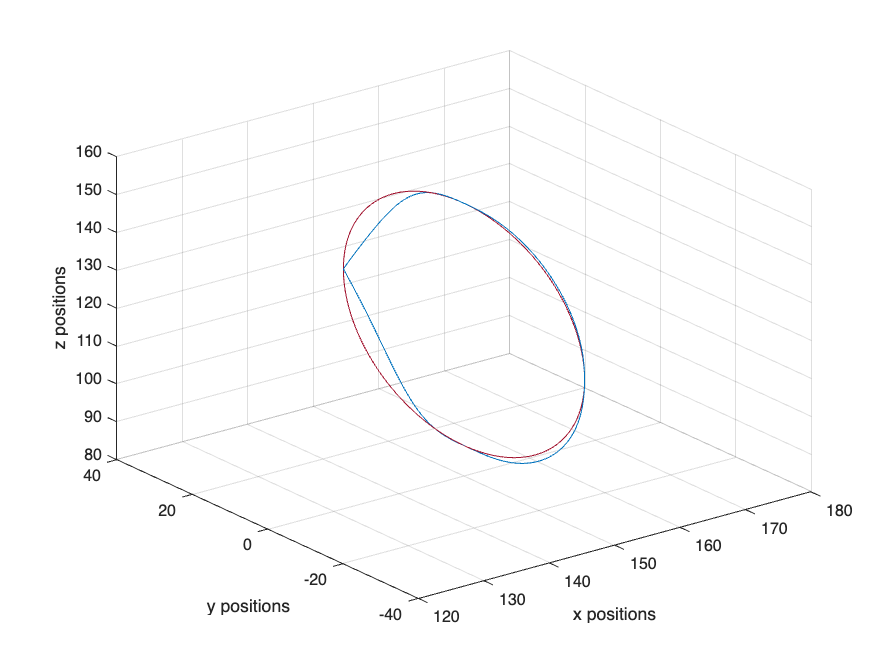




figure(2)
plot3(xpos, ypos, zpos)
hold on
plot3(x,y,z)
grid on
xlabel('x positions')
ylabel('y positions')
zlabel('z positions')

xlim([120 180])

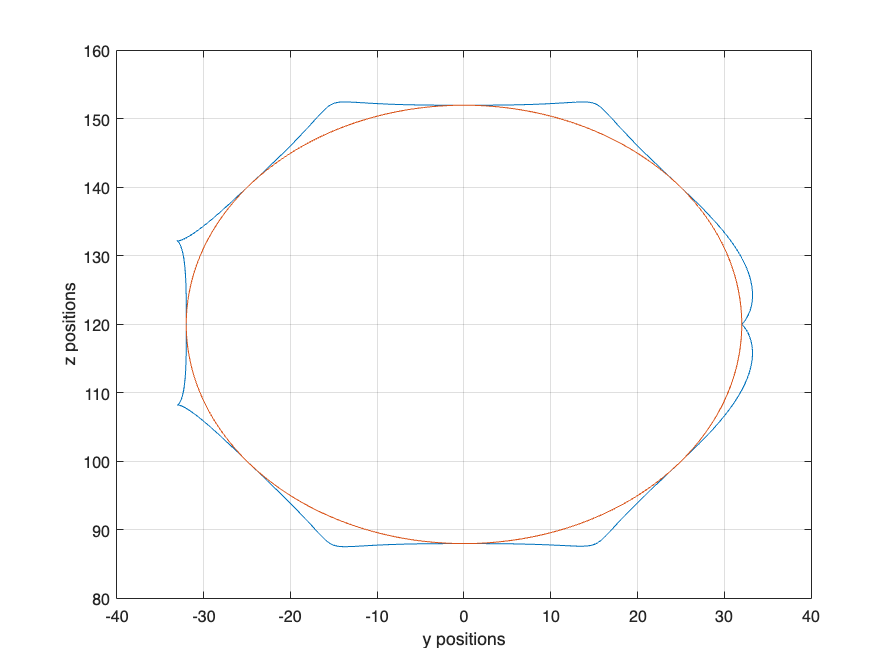

%Problem 7 after optimization we do the same thing as prbm 6 with more
%points
syms A10 A11 A12 A13 A14 A15;
l0_bis= [0;0;0;0;0;0];
l1_bis = [0;-25*cos(5*pi/18);25*sin(5*pi/18);0;0;0];
qdot0_bis = J4_1\l0_bis;
qdot1_bis = J4_pi4\l1_bis;
Y= [1 0 0 0 0 0; 0 1 0 0 0 0; 0 0 2 0 0 0; 1 2 4 8 16 32; 0 1 4 12 32 80; 0 0 2 12 48 160];
res = [thetas_2_rad(1,1); qdot0_bis(1,1); 0; thetas_2_rad(5,1); qdot1_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

syms A20 A21 A22 A23 A24 A25;
res = [thetas_2_rad(1,2); qdot0_bis(2,1); 0; thetas_2_rad(5,2); qdot1_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

syms A30 A31 A32 A33 A34 A35;
res = [thetas_2_rad(1,3); qdot0_bis(3,1); 0; thetas_2_rad(5,3); qdot1_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

syms A40 A41 A42 A43 A44 A45;
res = [thetas_2_rad(1,4); qdot0_bis(4,1); 0; thetas_2_rad(5,4); qdot1_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

A_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];

%------B-------------------------------------------------------------------

l1_bis = [0;-25*cos(5*pi/18);25*sin(5*pi/18);0;0;0];
l2_bis= [0;-25;0;0;0;0];
qdot1_bis = J4_pi4\l1_bis;
qdot2_bis = J4_2\l2_bis;
res = [thetas_2_rad(5,1); qdot1_bis(1,1); 0; thetas_2_rad(10,1); qdot2_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(5,2); qdot1_bis(2,1); 0; thetas_2_rad(10,2); qdot2_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(5,3); qdot1_bis(3,1); 0; thetas_2_rad(10,3); qdot2_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

res = [thetas_2_rad(5,4); qdot1_bis(4,1); 0; thetas_2_rad(10,4); qdot2_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

B_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];

%-----------__C-------------------------------------------------------------------

l2_bis= [0;-25;0;0;0;0];
l3_bis = [0;-25*cos(5*pi/18);-25*sin(5*pi/18);0;0;0];
qdot2_bis = J4_2\l2_bis;
qdot3_bis = J4_3pi4\l3_bis;
res = [thetas_2_rad(10,1); qdot2_bis(1,1); 0; thetas_2_rad(15,1); qdot3_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(10,2); qdot2_bis(2,1); 0; thetas_2_rad(15,2); qdot3_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(10,3); qdot2_bis(3,1); 0; thetas_2_rad(15,3); qdot3_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

res = [thetas_2_rad(10,4); qdot2_bis(4,1); 0; thetas_2_rad(15,4); qdot3_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

C_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];

%---------------__D-----------------------------------------------------------

l3_bis = [0;-25*cos(5*pi/18);-25*sin(5*pi/18);0;0;0];
l4_bis=[0;0;-25;0;0;0];
qdot3_bis = J4_3pi4\l3_bis;
qdot4_bis = J4_pi\l4_bis;
res = [thetas_2_rad(15,1); qdot3_bis(1,1); 0; thetas_2_rad(19,1); qdot4_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(15,2); qdot3_bis(2,1); 0; thetas_2_rad(19,2); qdot4_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(15,3); qdot3_bis(3,1); 0; thetas_2_rad(19,3); qdot4_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);


res = [thetas_2_rad(15,4); qdot3_bis(4,1); 0; thetas_2_rad(19,4); qdot4_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

D_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];


l4_bis=[0;0;-25;0;0;0];
l5_bis = [0;25*cos(5*pi/18);-25*sin(5*pi/18);0;0;0];
qdot4_bis = J4_pi\l4_bis;
qdot5_bis = J4_5pi4\l5_bis;
Y= [1 0 0 0 0 0; 0 1 0 0 0 0; 0 0 2 0 0 0; 1 2 4 8 16 32; 0 1 4 12 32 80; 0 0 2 12 48 160];
res = [thetas_2_rad(19,1); qdot4_bis(1,1); 0; thetas_2_rad(23,1); qdot5_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

syms A20 A21 A22 A23 A24 A25;
res = [thetas_2_rad(19,2); qdot4_bis(2,1); 0; thetas_2_rad(23,2); qdot5_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

syms A30 A31 A32 A33 A34 A35;
res = [thetas_2_rad(19,3); qdot4_bis(3,1); 0; thetas_2_rad(23,3); qdot5_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

syms A40 A41 A42 A43 A44 A45;
res = [thetas_2_rad(19,4); qdot4_bis(4,1); 0; thetas_2_rad(23,4); qdot5_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

E_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];

%------B-------------------------------------------------------------------

l5_bis = [0;25*cos(5*pi/18);-25*sin(5*pi/18);0;0;0];
l6_bis =[0;25;0;0;0;0];
qdot5_bis = J4_5pi4\l5_bis;
qdot6_bis = J4_3\l6_bis;
res = [thetas_2_rad(23,1); qdot5_bis(1,1); 0; thetas_2_rad(28,1); qdot6_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(23,2); qdot5_bis(2,1); 0; thetas_2_rad(28,2); qdot6_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(23,3); qdot5_bis(3,1); 0; thetas_2_rad(28,3); qdot6_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

res = [thetas_2_rad(23,4); qdot5_bis(4,1); 0; thetas_2_rad(28,4); qdot6_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

F_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];

%-----------__C-------------------------------------------------------------------

l6_bis =[0;25;0;0;0;0];
l7_bis = [0;25*cos(5*pi/18);25*sin(5*pi/18);0;0;0];
qdot6_bis = J4_3\l6_bis;
qdot7_bis = J4_7pi4\l7_bis;
res = [thetas_2_rad(28,1); qdot6_bis(1,1); 0; thetas_2_rad(33,1); qdot7_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(28,2); qdot6_bis(2,1); 0; thetas_2_rad(33,2); qdot7_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(28,3); qdot6_bis(3,1); 0; thetas_2_rad(33,3); qdot7_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

res = [thetas_2_rad(28,4); qdot6_bis(4,1); 0; thetas_2_rad(33,4); qdot7_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

G_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];
%---------------__D-----------------------------------------------------------

l7_bis = [0;25*cos(5*pi/18);25*sin(5*pi/18);0;0;0];
l8_bis = [0;0;0;0;0;0];
qdot7_bis = J4_7pi4\l7_bis;
qdot8_bis = J4_1\l8_bis;
res = [thetas_2_rad(33,1); qdot7_bis(1,1); 0; thetas_2_rad(37,1); qdot8_bis(1,1); 0];
res = Y\res;
A10 = res(1,1);
A11 = res(2,1);
A12 = res(3,1);
A13 = res(4,1);
A14 = res(5,1);
A15 = res(6,1);

res = [thetas_2_rad(33,2); qdot7_bis(2,1); 0; thetas_2_rad(37,2); qdot8_bis(2,1); 0];
res = Y\res;
A20 = res(1,1);
A21 = res(2,1);
A22 = res(3,1);
A23 = res(4,1);
A24 = res(5,1);
A25 = res(6,1);

res = [thetas_2_rad(33,3); qdot7_bis(3,1); 0; thetas_2_rad(37,3); qdot8_bis(3,1); 0];
res = Y\res;
A30 = res(1,1);
A31 = res(2,1);
A32 = res(3,1);
A33 = res(4,1);
A34 = res(5,1);
A35 = res(6,1);

res = [thetas_2_rad(33,4); qdot7_bis(4,1); 0; thetas_2_rad(37,4); qdot8_bis(4,1); 0];
res = Y\res;
A40 = res(1,1);
A41 = res(2,1);
A42 = res(3,1);
A43 = res(4,1);
A44 = res(5,1);
A45 = res(6,1);

H_bis =[A10 A11 A12 A13 A14 A15; A20 A21 A22 A23 A24 A25; A30 A31 A32 A33 A34 A35; A40 A41 A42 A43 A44 A45];
t1_bis = linspace(0, 2, 100);

q1_1_bis = A_bis(1,1)+A_bis(1,2).*t1_bis+A_bis(1,3).*t1_bis.^2+A_bis(1,4)*t1_bis.^3+A_bis(1,5).*t1_bis.^4+A_bis(1,6).*t1_bis.^5;
q2_1_bis = A_bis(2,1)+A_bis(2,2).*t1_bis+A_bis(2,3).*t1_bis.^2+A_bis(2,4)*t1_bis.^3+A_bis(2,5).*t1_bis.^4+A_bis(2,6).*t1_bis.^5;
q3_1_bis = A_bis(3,1)+A_bis(3,2).*t1_bis+A_bis(3,3).*t1_bis.^2+A_bis(3,4)*t1_bis.^3+A_bis(3,5).*t1_bis.^4+A_bis(3,6).*t1_bis.^5;
q4_1_bis = A_bis(4,1)+A_bis(4,2).*t1_bis+A_bis(4,3).*t1_bis.^2+A_bis(4,4)*t1_bis.^3+A_bis(4,5).*t1_bis.^4+A_bis(4,6).*t1_bis.^5;

%t1 = linspace(2, 4, 50);
q1_2_bis = B_bis(1,1)+B_bis(1,2).*t1_bis+B_bis(1,3).*t1_bis.^2+B_bis(1,4)*t1_bis.^3+B_bis(1,5).*t1_bis.^4+B_bis(1,6).*t1_bis.^5;
q2_2_bis = B_bis(2,1)+B_bis(2,2).*t1_bis+B_bis(2,3).*t1_bis.^2+B_bis(2,4)*t1_bis.^3+B_bis(2,5).*t1_bis.^4+B_bis(2,6).*t1_bis.^5;
q3_2_bis = B_bis(3,1)+B_bis(3,2).*t1_bis+B_bis(3,3).*t1_bis.^2+B_bis(3,4)*t1_bis.^3+B_bis(3,5).*t1_bis.^4+B_bis(3,6).*t1_bis.^5;
q4_2_bis = B_bis(4,1)+B_bis(4,2).*t1_bis+B_bis(4,3).*t1_bis.^2+B_bis(4,4)*t1_bis.^3+B_bis(4,5).*t1_bis.^4+B_bis(4,6).*t1_bis.^5;

%t1 = linspace(4, 6, 50);
q1_3_bis = C_bis(1,1)+C_bis(1,2).*t1_bis+C_bis(1,3).*t1_bis.^2+C_bis(1,4)*t1_bis.^3+C_bis(1,5).*t1_bis.^4+C_bis(1,6).*t1_bis.^5;
q2_3_bis = C_bis(2,1)+C_bis(2,2).*t1_bis+C_bis(2,3).*t1_bis.^2+C_bis(2,4)*t1_bis.^3+C_bis(2,5).*t1_bis.^4+C_bis(2,6).*t1_bis.^5;
q3_3_bis = C_bis(3,1)+C_bis(3,2).*t1_bis+C_bis(3,3).*t1_bis.^2+C_bis(3,4)*t1_bis.^3+C_bis(3,5).*t1_bis.^4+C_bis(3,6).*t1_bis.^5;
q4_3_bis = C_bis(4,1)+C_bis(4,2).*t1_bis+C_bis(4,3).*t1_bis.^2+C_bis(4,4)*t1_bis.^3+C_bis(4,5).*t1_bis.^4+C_bis(4,6).*t1_bis.^5;


%t1 = linspace(6, 8, 50);
q1_4_bis = D_bis(1,1)+D_bis(1,2).*t1_bis+D_bis(1,3).*t1_bis.^2+D_bis(1,4)*t1_bis.^3+D_bis(1,5).*t1_bis.^4+D_bis(1,6).*t1_bis.^5;
q2_4_bis = D_bis(2,1)+D_bis(2,2).*t1_bis+D_bis(2,3).*t1_bis.^2+D_bis(2,4)*t1_bis.^3+D_bis(2,5).*t1_bis.^4+D_bis(2,6).*t1_bis.^5;
q3_4_bis = D_bis(3,1)+D_bis(3,2).*t1_bis+D_bis(3,3).*t1_bis.^2+D_bis(3,4)*t1_bis.^3+D_bis(3,5).*t1_bis.^4+D_bis(3,6).*t1_bis.^5;
q4_4_bis = D_bis(4,1)+D_bis(4,2).*t1_bis+D_bis(4,3).*t1_bis.^2+D_bis(4,4)*t1_bis.^3+D_bis(4,5).*t1_bis.^4+D_bis(4,6).*t1_bis.^5;


q1_5_bis = E_bis(1,1)+E_bis(1,2).*t1_bis+E_bis(1,3).*t1_bis.^2+E_bis(1,4)*t1_bis.^3+E_bis(1,5).*t1_bis.^4+E_bis(1,6).*t1_bis.^5;
q2_5_bis = E_bis(2,1)+E_bis(2,2).*t1_bis+E_bis(2,3).*t1_bis.^2+E_bis(2,4)*t1_bis.^3+E_bis(2,5).*t1_bis.^4+E_bis(2,6).*t1_bis.^5;
q3_5_bis = E_bis(3,1)+E_bis(3,2).*t1_bis+E_bis(3,3).*t1_bis.^2+E_bis(3,4)*t1_bis.^3+E_bis(3,5).*t1_bis.^4+E_bis(3,6).*t1_bis.^5;
q4_5_bis = E_bis(4,1)+E_bis(4,2).*t1_bis+E_bis(4,3).*t1_bis.^2+E_bis(4,4)*t1_bis.^3+E_bis(4,5).*t1_bis.^4+E_bis(4,6).*t1_bis.^5;


q1_6_bis = F_bis(1,1)+F_bis(1,2).*t1_bis+F_bis(1,3).*t1_bis.^2+F_bis(1,4)*t1_bis.^3+F_bis(1,5).*t1_bis.^4+F_bis(1,6).*t1_bis.^5;
q2_6_bis = F_bis(2,1)+F_bis(2,2).*t1_bis+F_bis(2,3).*t1_bis.^2+F_bis(2,4)*t1_bis.^3+F_bis(2,5).*t1_bis.^4+F_bis(2,6).*t1_bis.^5;
q3_6_bis = F_bis(3,1)+F_bis(3,2).*t1_bis+F_bis(3,3).*t1_bis.^2+F_bis(3,4)*t1_bis.^3+F_bis(3,5).*t1_bis.^4+F_bis(3,6).*t1_bis.^5;
q4_6_bis = F_bis(4,1)+F_bis(4,2).*t1_bis+F_bis(4,3).*t1_bis.^2+F_bis(4,4)*t1_bis.^3+F_bis(4,5).*t1_bis.^4+F_bis(4,6).*t1_bis.^5;

q1_7_bis = G_bis(1,1)+G_bis(1,2).*t1_bis+G_bis(1,3).*t1_bis.^2+G_bis(1,4)*t1_bis.^3+G_bis(1,5).*t1_bis.^4+G_bis(1,6).*t1_bis.^5;
q2_7_bis = G_bis(2,1)+G_bis(2,2).*t1_bis+G_bis(2,3).*t1_bis.^2+G_bis(2,4)*t1_bis.^3+G_bis(2,5).*t1_bis.^4+G_bis(2,6).*t1_bis.^5;
q3_7_bis = G_bis(3,1)+G_bis(3,2).*t1_bis+G_bis(3,3).*t1_bis.^2+G_bis(3,4)*t1_bis.^3+G_bis(3,5).*t1_bis.^4+G_bis(3,6).*t1_bis.^5;
q4_7_bis = G_bis(4,1)+G_bis(4,2).*t1_bis+G_bis(4,3).*t1_bis.^2+G_bis(4,4)*t1_bis.^3+G_bis(4,5).*t1_bis.^4+G_bis(4,6).*t1_bis.^5;


q1_8_bis = H_bis(1,1)+H_bis(1,2).*t1_bis+H_bis(1,3).*t1_bis.^2+H_bis(1,4)*t1_bis.^3+H_bis(1,5).*t1_bis.^4+H_bis(1,6).*t1_bis.^5;
q2_8_bis = H_bis(2,1)+H_bis(2,2).*t1_bis+H_bis(2,3).*t1_bis.^2+H_bis(2,4)*t1_bis.^3+H_bis(2,5).*t1_bis.^4+H_bis(2,6).*t1_bis.^5;
q3_8_bis = H_bis(3,1)+H_bis(3,2).*t1_bis+H_bis(3,3).*t1_bis.^2+H_bis(3,4)*t1_bis.^3+H_bis(3,5).*t1_bis.^4+H_bis(3,6).*t1_bis.^5;
q4_8_bis = H_bis(4,1)+H_bis(4,2).*t1_bis+H_bis(4,3).*t1_bis.^2+H_bis(4,4)*t1_bis.^3+H_bis(4,5).*t1_bis.^4+H_bis(4,6).*t1_bis.^5;


q1_bis = [q1_1_bis, q1_2_bis, q1_3_bis, q1_4_bis, q1_5_bis, q1_6_bis, q1_7_bis, q1_8_bis];
q2_bis = [q2_1_bis, q2_2_bis, q2_3_bis, q2_4_bis, q2_5_bis, q2_6_bis, q2_7_bis, q2_8_bis];
q3_bis = [q3_1_bis, q3_2_bis, q3_3_bis, q3_4_bis, q3_5_bis, q3_6_bis, q3_7_bis, q3_8_bis];
q4_bis = [q4_1_bis, q4_2_bis, q4_3_bis, q4_4_bis, q4_5_bis, q4_6_bis, q4_7_bis, q4_8_bis];

xpos = zeros(length(q1_bis),1);
ypos = zeros(length(q1_bis),1);
zpos = zeros(length(q1_bis),1);

syms thet1 thet2 thet3 thet4
computeT04(thet1, thet2, thet3, thet4);


for k=1:length(q1_bis)

Result = computeT04(q1_bis(1,k), q2_bis(1,k), q3_bis(1,k), q4_bis(1,k));
xpos(k,1) = Result(1, 4);
ypos(k,1) = Result(2, 4);
zpos(k,1) = Result(3, 4);

end 

xpos;
ypos;
zpos;
r=32;
teta=-pi:0.01:pi;
ll = length(teta);
x = 150*ones(ll);
y=r*cos(teta);
z=120+r*sin(teta);

figure(9)
plot(ypos, zpos)
hold on 
plot(y,z)
grid on
xlabel('y positions')
ylabel('z positions')

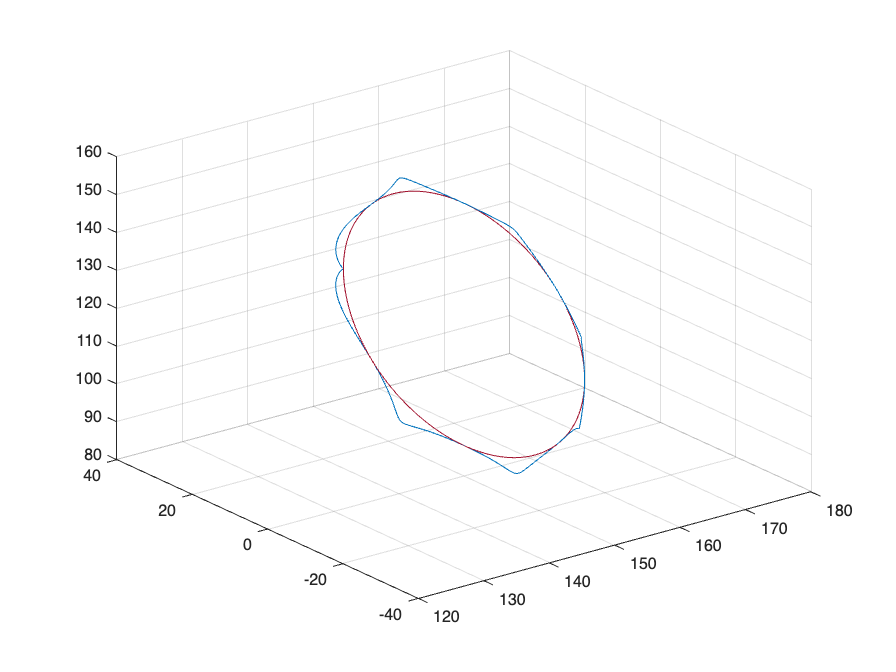



figure(10)
plot3(xpos, ypos, zpos)
hold on
r=32;
teta=-pi:0.01:pi;
length(teta);
ll = 2*pi/0.01+1;
x = 150*ones(629);
y=r*cos(teta);
z=120+r*sin(teta);
plot3(x,y,z)
grid on
xlim([120 180])

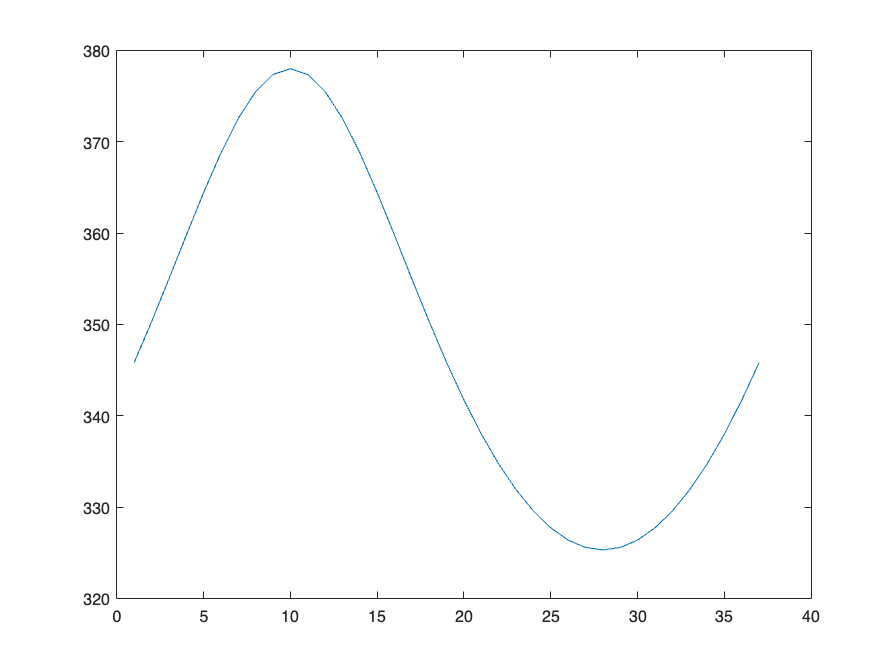

%Problem 8 
%Calculate condition number along path of prblm 3 & prblm 6
condition_numbers_pb3 = zeros(37, 1);
length(q1);
condition_numbers_pb6 = zeros(length(q1), 1);
for k=1:37
    [J4_ J5_] = JacobianMatrix(thetas_2_rad(k,1), thetas_2_rad(k,2), thetas_2_rad(k,3), thetas_2_rad(k,4));
    condition_numbers_pb3(k,1) = cond(J4_);
end

figure(26)
plot(condition_numbers_pb3)

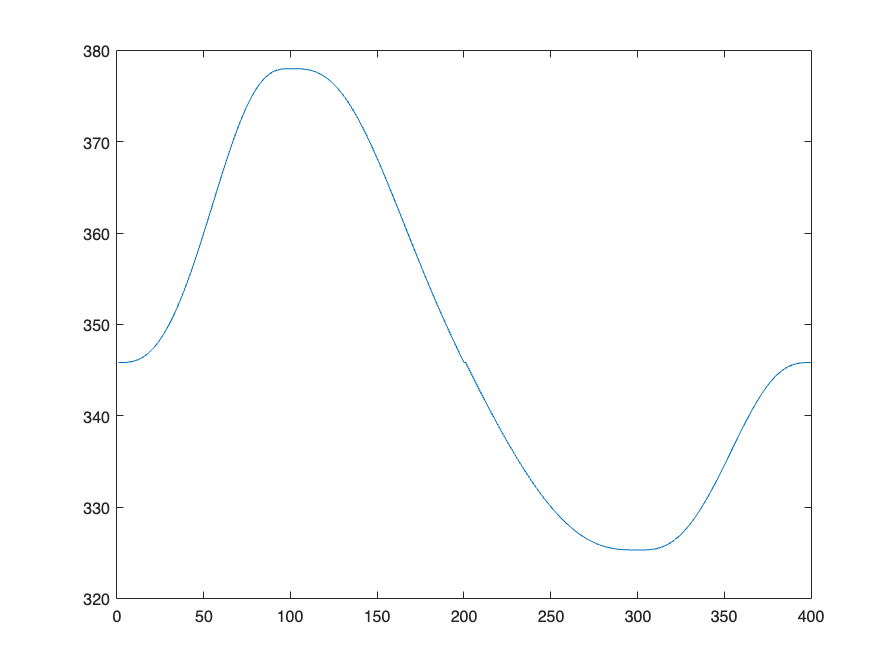


for k=1:length(q1)
    [J4_ J5_] = JacobianMatrix(q1(1,k), q2(1,k), q3(1,k), q4(1,k));
    condition_numbers_pb6(k,1) = cond(J4_);
end

figure(42)
plot(condition_numbers_pb6)

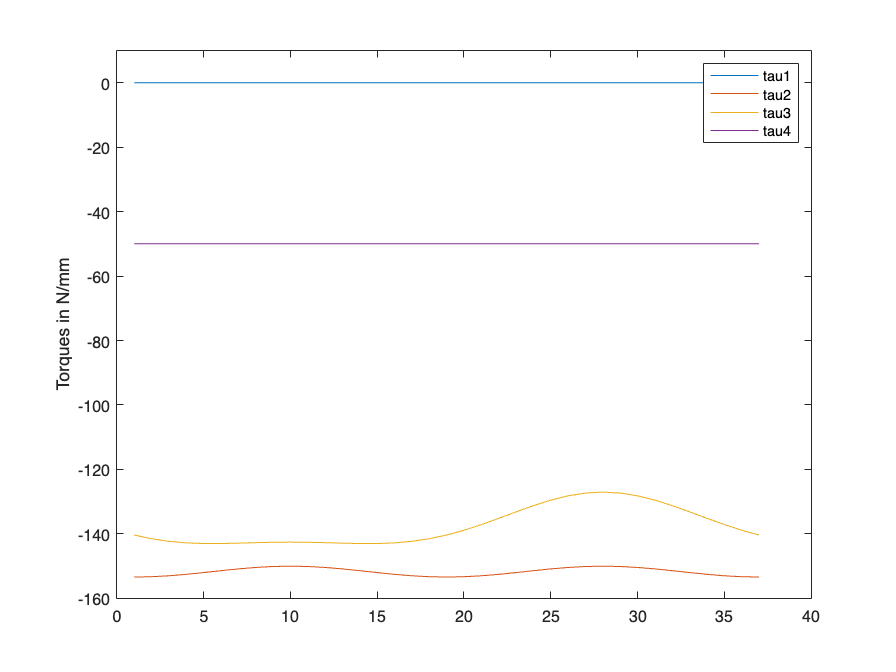

%Problem 9 

torque1_pb3 = zeros(37,1);
torque2_pb3 = zeros(37,1);
torque3_pb3 = zeros(37,1);
torque4_pb3 = zeros(37,1);

torque1_pb6 = zeros(length(q1),1);
torque2_pb6 = zeros(length(q1),1);
torque3_pb6 = zeros(length(q1),1);
torque4_pb6 = zeros(length(q1),1);

F = [0; 0; -1; 0; 0; 0]; % Define force applied on the segments 
%Calculate torques 
for k=1:37
    [J_1, J_2, J_3, J_4, J_5] = JacobianMatrixv2(thetas_2_rad(k,1), thetas_2_rad(k,2), thetas_2_rad(k,3), thetas_2_rad(k,4));
    torque1_pb3(k,1) = (J_1')*F;
    torque2_pb3(k,1) = (J_2(:,2))'*F;
    torque3_pb3(k,1) = (J_3(:,3))'*F;
    torque4_pb3(k,1) = (J_4(:,4))'*F;
end



for k=1:length(q1)
    [J_1, J_2, j_3, J_4 J_5] = JacobianMatrixv2(q1(1,k), q2(1,k), q3(1,k), q4(1,k));
    torque1_pb6(k,1) = (J_1')*F;
    torque2_pb6(k,1) = (J_2(:,2))'*F;
    torque3_pb6(k,1) = (J_3(:,3))'*F;
    torque4_pb6(k,1) = (J_4(:,4))'*F;
end



torque_pb3 = [torque1_pb3, torque2_pb3, torque3_pb3, torque4_pb3];
torque_pb6 = [torque1_pb6, torque2_pb6, torque3_pb6, torque4_pb6];

figure(3)
plot(torque_pb3)
legend('tau1', 'tau2', 'tau3', 'tau4')
ylabel('Torques in N/mm')
ylim([-160 10])

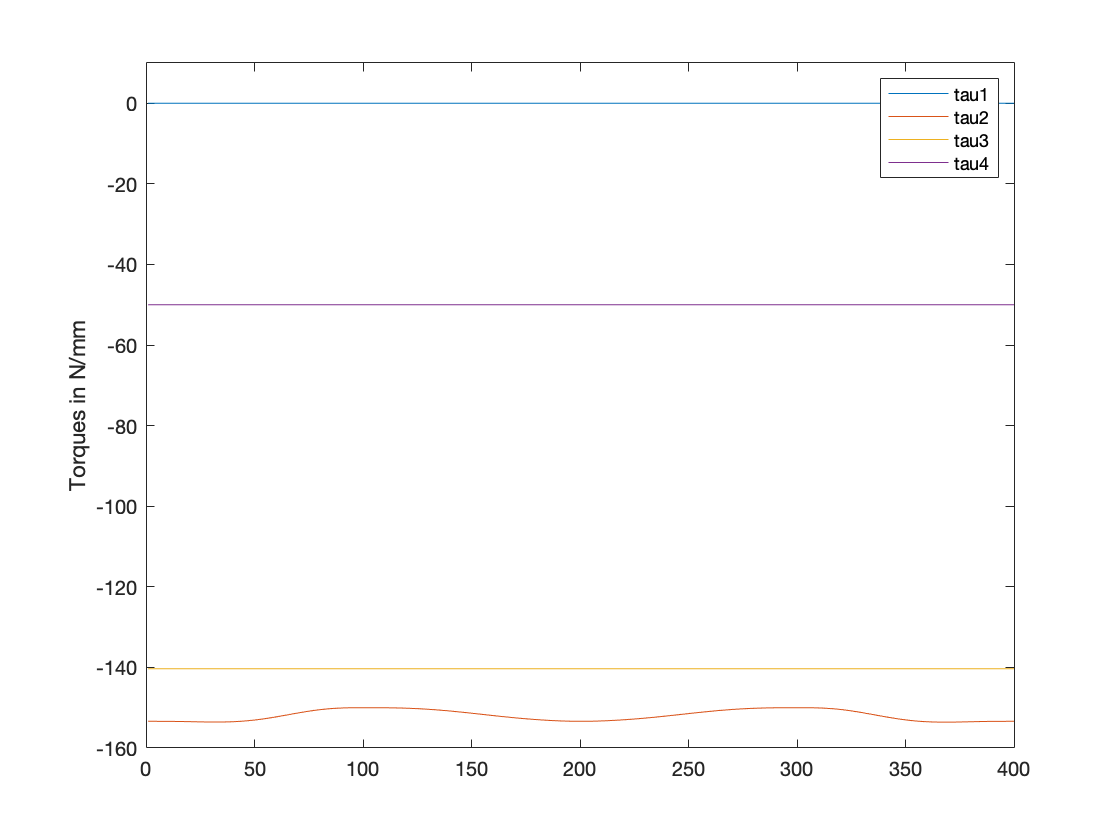

figure(4)
plot(torque_pb6)
ylim([-160 10])
ylabel('Torques in N/mm')
legend('tau1', 'tau2', 'tau3', 'tau4')

function [x, y, z] = circleCoordinates(angle)
    n_angles = length(angle);
    p_0 = [150*ones(1,n_angles); zeros(1,n_angles); 120*ones(1,n_angles)]' ...
           +32*[zeros(1,n_angles); cos(angle)'; sin(angle)']';
    x = p_0(:,1);
    y = p_0(:,2);
    z = p_0(:,3);
end

function[R01, R02, R03, R04] = computeR(theta1, theta2, theta3, theta4)

c1 = cos(theta1); s1 = sin(theta1);
c2 = cos(theta2); s2 = sin(theta2);
c3 = cos(theta3); s3 = sin(theta3);
c4 = cos(theta4); s4 = sin(theta4);
%% Computes the Ti
R01 = [c1 0 s1 ;
    s1 0 -c1 ;
    0 1 0 ];

R12 = [c2 -s2 0 ;
    s2 c2 0 ;
    0 0 1 ];

R23 = [c3 -s3 0 ;
    s3 c3 0;
    0 0 1 ];

R34 = [c4 -s4 0;
    s4 c4 0 ;
    0 0 1 ];

R45 = [1 0 0 
    0 1 0 
    0 0 1];

%% Computes T0i

R02 = R01*R12;
R03 = R02*R23;
R04 = R03*R34;
R05 = R04*R45;
end 

function[T04] = computeT04(theta1, theta2, theta3, theta4)

c1 = cos(theta1); s1 = sin(theta1);
c2 = cos(theta2); s2 = sin(theta2);
c3 = cos(theta3); s3 = sin(theta3);
c4 = cos(theta4); s4 = sin(theta4);
%% Computes the Ti
T01 = [c1 0 s1 0;
    s1 0 -c1 0;
    0 1 0 50
    0 0 0 1];

T12 = [c2 -s2 0 93*c2;
    s2 c2 0 93*s2;
    0 0 1 0;
    0 0 0 1];

T23 = [c3 -s3 0 93*c3;
    s3 c3 0 93*s3;
    0 0 1 0;
    0 0 0 1];

T34 = [c4 -s4 0 50*c4;
    s4 c4 0 50*s4;
    0 0 1 0;
    0 0 0 1];

T45 = [1 0 0 -15
    0 1 0 45
    0 0 1 0
    0 0 0 1];

%% Computes T0i

T02 = T01*T12;
T03 = T02*T23;
T04 = T03*T34;
T05 = T04*T45;

end

function [T01, T12, T23, T34, T45] = homogeneousTransformationMatrices(theta1, theta2, theta3, theta4)
    % Define some variables
    c1 = cos(theta1); s1 = sin(theta1);
    c2 = cos(theta2); s2 = sin(theta2);
    c3 = cos(theta3); s3 = sin(theta3);
    c4 = cos(theta4); s4 = sin(theta4);
    %% Computes the Ti
    T01 = [c1 0 s1 0;
        s1 0 -c1 0;
        0 1 0 50
        0 0 0 1];
    
    T12 = [c2 -s2 0 93*c2;
        s2 c2 0 93*s2;
        0 0 1 0;
        0 0 0 1];
    
    T23 = [c3 -s3 0 93*c3;
        s3 c3 0 93*s3;
        0 0 1 0;
        0 0 0 1];
    
    T34 = [c4 -s4 0 50*c4;
        s4 c4 0 50*s4;
        0 0 1 0;
        0 0 0 1];
    
    T45 = [1 0 0 -15
        0 1 0 45
        0 0 1 0
        0 0 0 1];
end

function [J4, J5] = JacobianMatrix(theta1,theta2, theta3, theta4)

[T01, T12, T23, T34, T45] = homogeneousTransformationMatrices(theta1, theta2, theta3, theta4);

%% Computes T0i

T02 = T01*T12;
T03 = T02*T23;
T04 = T03*T34;
T05 = T04*T45;

%% Extract Parameters from T0i

z0 = [0 0 1]';
z1 = T01(1:3,3);
z2 = T02(1:3,3);
z3 = T03(1:3,3);
z4 = T04(1:3,3);
z5 = T05(1:3,3);

O0 = [0 0 0]';
O1 = T01(1:3,4);
O2 = T02(1:3,4);
O3 = T03(1:3,4);
O4 = T04(1:3,4);
O5 = T05(1:3,4);

%% Compute J4vi and J4wi for J4

J4v0 = cross(z0,(O4-O0));
J4w0 = z0;
J4v1 = cross(z1,(O4-O1));
J4w1 = z1;
J4v2 = cross(z2,(O4-O2));
J4w2 = z2;
J4v3 = cross(z3,(O4-O3));
J4w3 = z3;

%% Compute J4
J4 = [J4v0 J4v1 J4v2 J4v3; J4w0 J4w1 J4w2 J4w3];

%% Compute J5vi and J5wi for J5

J5v0 = cross(z0,(O5-O0));
J5w0 = z0;
J5v1 = cross(z1,(O5-O1));
J5w1 = z1;
J5v2 = cross(z2,(O5-O2));
J5w2 = z2;
J5v3 = cross(z3,(O5-O3));
J5w3 = z3;

%% Compute J5
J5 = [J5v0 J5v1 J5v2 J5v3; J5w0 J5w1 J5w2 J5w3];
end